clc; close all; clear all; warning off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
d_prime_s_res=0.2;  %% maximum distance resolution, m

tau_s_0=[0.01];  %%  threshold in sensing

% r_c_com=0.5e9;  %% %% threshold/required data rate in communication, minimum communictaion data rate, 1Gbps

gamma_bs_0= [10:10:300]/1000^2;  %%  density of base station, point/m^2

gamma_sct= 300/1000^2; %% density of SCT, point/m^2

gamma_st= 300/1000^2;   %% density of ST, point/m^2

eta=0.5;  %% first \beta part of the spectrum is allocated to sensing

mu=0.5;  %%  first \mu part of the power is allocated to sensing

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
run('parameters.mlx');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Ana_P_s_cov_2=zeros(size(tau_s_0,2),size(gamma_bs_0,2));
Sim_P_s_cov_2=zeros(size(tau_s_0,2),size(gamma_bs_0,2));

for tt=1:size(tau_s_0,2)
    for gg=1:size(gamma_bs_0,2)
        
        gamma_bs=gamma_bs_0(1,gg)
        tau_s=tau_s_0(1,tt);
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        L_cs1=@(d_tb) exp(-2*pi*gamma_bs*  integral(@(d_bjt) tau_s/(tau_s+(d_bjt/d_tb)^2)*d_bjt, d_tb, d_tb_max, "ArrayValued",true) );
        
        int_s1=@(d_tb,psi) integral(@(d_tit)  tau_s/(tau_s+  4*pi*d_tit^2*(d_tb^2+d_tit^2-2*d_tb*d_tit*cos(psi))/rho_sti/d_tb^2  *d_tit ), 0, d_tit_max, "ArrayValued",true );
        L_cs2=@(d_tb) exp(-gamma_st* integral(@(psi) int_s1(d_tb,psi), 0, 2*pi,"ArrayValued",true)  );
        
        int_s2= @(d_tb) exp(-tau_s*N_s/P_st/g_st/g_sr/rho_st/c^2/N_c/T_c*(4*pi)^3*f_s^2* d_tb^4  ) ...
            * L_cs1(d_tb)* L_cs2(d_tb)  *2*pi*gamma_bs*d_tb*exp(-pi*gamma_bs*d_tb^2);
        
        d_tb_max_prime=max(0,min(d_tb_max, c/2*(T_c-c*T_c/2/(B_s*1e6)/d_prime_s_res))); %% this is about the consideration of distance resolution
        
        Ana_P_s_cov_2(tt,gg)= integral(@(d_tb) int_s2(d_tb), 0, d_tb_max_prime, "ArrayValued",true);
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        iteration=100000;
        
        SCNR_s=zeros(1,iteration);
        parfor ii=1:iteration
            
            d_tb_max_prime=max(0,min(d_tb_max, c/2*(T_c-c*T_c/2/(B_s*1e6)/d_prime_s_res))); %% this is about the consideration of distance resolution
            
            [D_tb,D_bjt,D_tit,D_bti]=calculate_clutter(range_xy_BS,range_xy_ST,gamma_bs,gamma_st,d_tb_max,d_tb_max_prime, d_bjt_max,d_tit_max,d_bti_max);
            
            C_s1= P_st*g_st/4/pi./D_bjt.^2  *rho_st/4/pi/D_tb^2  *g_sr*c^2/f_s^2/4/pi  *N_c*T_c*exprnd(1);
            
            C_s2= P_st*g_st/4/pi./D_bti.^2  .*rho_sti/4/pi/D_tit.^2  *rho_st/4/pi/D_tb^2  *g_sr*c^2/f_s^2/4/pi  *N_c*T_c.*exprnd(1,1,length(D_bti));
            
            C_s=sum(C_s1)+sum(C_s2);
            
            P_sr_Dbt=P_st*g_st/4/pi/D_tb^2 *rho_st/4/pi/D_tb^2 *g_sr*c^2/4/pi/f_s^2 *N_c*T_c*exprnd(1);
            
            SCNR_s(1,ii)=P_sr_Dbt/(N_s+C_s);
            
        end
        
        Sim_P_s_cov_2(tt,gg)=sum(SCNR_s >= tau_s)/iteration;
    end
    
end

gamma_bs = 1.0000e-05

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 20).


gamma_bs = 2.0000e-05

gamma_bs = 3.0000e-05

gamma_bs = 4.0000e-05

gamma_bs = 5.0000e-05

gamma_bs = 6.0000e-05

gamma_bs = 7.0000e-05

gamma_bs = 8.0000e-05

gamma_bs = 9.0000e-05

gamma_bs = 1.0000e-04

gamma_bs = 1.1000e-04

gamma_bs = 1.2000e-04

gamma_bs = 1.3000e-04

gamma_bs = 1.4000e-04

gamma_bs = 1.5000e-04

gamma_bs = 1.6000e-04

gamma_bs = 1.7000e-04

gamma_bs = 1.8000e-04

gamma_bs = 1.9000e-04

gamma_bs = 2.0000e-04

gamma_bs = 2.1000e-04

gamma_bs = 2.2000e-04

gamma_bs = 2.3000e-04

gamma_bs = 2.4000e-04

gamma_bs = 2.5000e-04

gamma_bs = 2.6000e-04

gamma_bs = 2.7000e-04

gamma_bs = 2.8000e-04

gamma_bs = 2.9000e-04

gamma_bs = 3.0000e-04

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

save('data/Ana_P_s_cov_2.mat','Ana_P_s_cov_2');
save('data/Sim_P_s_cov_2.mat','Sim_P_s_cov_2');

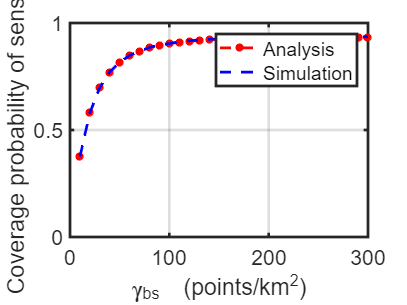


for tt=1:size(tau_s_0,2)
    figure();
    plot(gamma_bs_0*1000^2, Ana_P_s_cov_2(tt,:),'--*r','LineWidth',2);hold on;
    plot(gamma_bs_0*1000^2, Sim_P_s_cov_2(tt,:),'--b','LineWidth',2);hold on;
    
    legend('Analysis','Simulation');
    xlabel('\gamma_{bs}  (points/km^2)');
    ylabel('Coverage probability of sensing' );
    ylim([0,1]);
    set(gca,'LineWidth',2,'FontSize',16);
    grid on;
    hold off;
end